% Заметки по лабораторной работе, которые должны пойти в отчет:
% 1) В абсолютно всех ресурсах, которые я встречал, говорилось, что для
% масштабирования, для каждой координаты помещаем в единичную матрицу S,
% хотя если они одниаковые, то можно было просто для 4 элемента поставить
% S, но судя по всему, поскольку координата w используется для других
% вещей, так лучше не делать
% 2) https://www.youtube.com/watch?v=o1n02xKP138 -- здесь активно
% продвигается идея про то, что для позиций (точек, например) w = 1, а для
% направлений w = 0. Это неформально, так что хз, как писать это в своем
% отчете.
% 3) Матрицы 2в поворота коммутируют, т.к. они все имеют вид
% [ cos(phi) -sin(phi) 0;
%   sin(phi)  cos(phi) 0;
%      0         0     1 ]
% Типа там не много вариантов, вокруг чего можно вращать.
% Для 3d не коммутирует, т.к. не сопадают собственные вектора
% 4) 

% https://www.cs.colostate.edu/~cs410/yr2018fa/more_progress/pdfs/cs410_F18_Lecture04_Trans_part2.pdf

verticesCube = [
 0, 0, 0, 0, 1, 1, 1, 1;
 0, 0, 1, 1, 0, 0, 1, 1;
 0, 1, 0, 1, 0, 1, 0, 1;
 1, 1, 1, 1, 1, 1, 1, 1
];

facesCube = [
    1, 3, 7, 5;
    2, 4, 8, 6;
    1, 5, 6, 2;
    1, 2, 4, 3;
    3, 4, 8, 7;
    7, 8, 6, 5;
];

% PlotShape(verticesCube, facesCube, 'blue');

% Plot 3d piramid

% verticesPiramid = [
%     4,-4, 0,    0;
%    -4,-4, 3.46, 0;
%     0, 0, 0,    4;
%     1, 1, 1,    1
% ];
% 
% facesPiramid = [
%     1, 2, 4;
%     1, 3, 4;
%     2, 3, 4;
%     1, 2, 3
% ];
% 
% PlotShape(verticesPiramid, facesPiramid, 'blue');

% Transfromation block
% How to scale an object:

% scaleMatrix = [
%     2, 0,  0,  0;
%     0, 3,  0,  0;
%     0, 0, 1/2, 0;
%     0, 0,  0,  1
% ];
% 
% scaledVerticesCube = scaleMatrix * verticesCube;
% 
% PlotShape(verticesCube, facesCube, 'blue');
% PlotShape(scaledVerticesCube, facesCube, 'red')

% How to translate an object:
% To get such matrix, you need to substrack start postition from end
% position.

% translationMatrix = [
%     1, 0, 0, 4;
%     0, 1, 0, 2;
%     0, 0, 1, 3;
%     0, 0, 0, 1
% ];
% translatedVerticesCube = translationMatrix * verticesCube;
% 
% PlotShape(verticesCube, facesCube, 'blue');
% PlotShape(translatedVerticesCube, facesCube, 'red');

% How to rotate an object
% Around x and y axes:

% rotatedVerticesCube = RotationMatrix(pi/5, 'x') * RotationMatrix(pi/4, 'y') *  verticesCube;
% 
% PlotShape(verticesCube, facesCube, 'blue');
% PlotShape(rotatedVerticesCube, facesCube, 'red');

% How to rotate an object around one of its vertices
% First translate vertice to origin, rotate and translate back
% 
% vertice = verticesCube(:, 3)
% 
% translateOrigin = [[
%     1, 0, 0;
%     0, 1, 0;
%     0, 0, 1;
%     0, 0, 0
% ], [-vertice(1:3, :); 1]];
% rotationMatrix = RotationMatrix(-pi/5, 'z') * RotationMatrix(pi/1.5, 'y') * RotationMatrix(pi/13, 'x');
% translateBack = [[
%     1, 0, 0;
%     0, 1, 0;
%     0, 0, 1;
%     0, 0, 0
% ], vertice];
% completeTransform = translateBack * rotationMatrix * translateOrigin;
% transformedVerticesCube = completeTransform * verticesCube;
% 
% PlotShape(verticesCube, facesCube, 'blue');
% PlotShape(transformedVerticesCube, facesCube, 'red');

% How to make a camera (no perspective, just projection)
cubes = {
    [verticesCube(1:2, :) - 1.5;
    verticesCube(3, :);
    verticesCube(4, :)], [verticesCube(1, :) + 1.5;
     verticesCube(2, :);
     verticesCube(3, :) - 3;
     verticesCube(4, :)], [verticesCube(1, :) - 1.5;
     verticesCube(2, :);
     verticesCube(3, :) - 3;
     verticesCube(4, :)]
};

cameraCords = [4; 4; 0];
cameraRotation = [deg2rad(0), deg2rad(60), deg2rad(30)];
cameraTranslate = [[
    1, 0, 0;
    0, 1, 0;
    0, 0, 1;
    0, 0, 0
], [-cameraCords; 1]];

cameraTransform = cameraTranslate / RotationMatrix(cameraRotation(1), 'x');
cameraTransform = cameraTransform / RotationMatrix(cameraRotation(2), 'y');
cameraTransform = cameraTransform / RotationMatrix(cameraRotation(3), 'z');

colors = {'blue' 'red' 'green'};
colors = string(colors);
for i=1:length(cubes)
    cellMatrix = cell2mat(cubes(i))
    cellMatrix = cameraTransform * cellMatrix;
    cellMatrix = [
        cellMatrix(1, :) + 2;
        cellMatrix(2, :) + 3;
        cellMatrix(3, :) - 2.5;
        cellMatrix(4, :)
    ];
    cubes(i) = {cellMatrix};
    PlotShape(cellMatrix, facesCube, colors(i));
end

cellMatrix =    -1.5000   -1.5000   -1.5000   -1.5000   -0.5000   -0.5000   -0.5000   -0.5000
   -1.5000   -1.5000   -0.5000   -0.5000   -1.5000   -1.5000   -0.5000   -0.5000
         0    1.0000         0    1.0000         0    1.0000         0    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


cellMatrix =     1.5000    1.5000    1.5000    1.5000    2.5000    2.5000    2.5000    2.5000
         0         0    1.0000    1.0000         0         0    1.0000    1.0000
   -3.0000   -2.0000   -3.0000   -2.0000   -3.0000   -2.0000   -3.0000   -2.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


cellMatrix =    -1.5000   -1.5000   -1.5000   -1.5000   -0.5000   -0.5000   -0.5000   -0.5000
         0         0    1.0000    1.0000         0         0    1.0000    1.0000
   -3.0000   -2.0000   -3.0000   -2.0000   -3.0000   -2.0000   -3.0000   -2.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


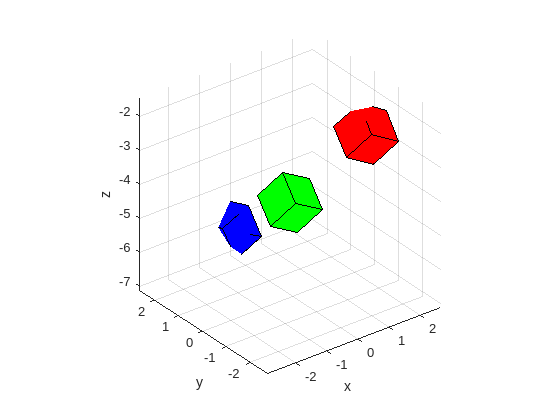

% view([0 90]);
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');

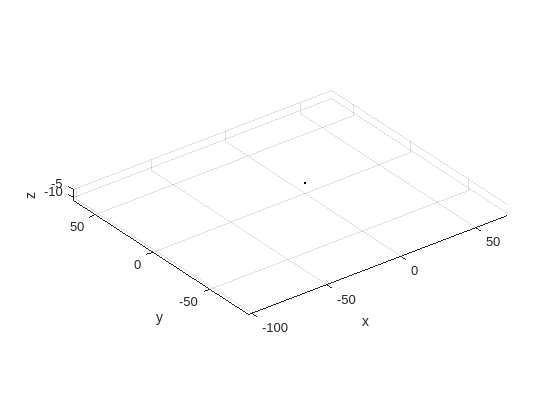

% My agony trying to achieve perspective

fov = deg2rad(60);
S = 1 / tan((fov * pi)/360);
n = -2; % n stands for Near Plane
f = -5; % f stands for Far Plane
perspectiveMatrix = [
    S, 0,         0,        0;
    0, S,         0,        0;
    0, 0,    -f/(n - f),   -1;
    0, 0, -(f*n)/(f - n),   0
];

for i=1:length(cubes)
    cubes(i) = {perspectiveMatrix * cell2mat(cubes(i))};
    PlotShape(cell2mat(cubes(i)), facesCube, colors(i));
end
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');

function DrawShape(vertices, faces, color)
    patch('Vertices', transpose(vertices(1:3, :)./vertices(4, :)), 'Faces', faces, 'FaceColor', color);
end

function PlotShape(vertices, faces, color)
    DrawShape(vertices, faces, color);

    axis equal;
    grid on;
    axis([ ...
        min(vertices(1, :)) - 2, max(vertices(1, :)) + 2, ...
        min(vertices(2, :)) - 2, max(vertices(2, :)) + 2, ...
        min(vertices(3, :)) - 2, max(vertices(3, :)) + 2, ...
    ]);
    xlabel('x'); ylabel('y'); zlabel('z');
    view(3);
end

function matrix = RotationMatrix(angle, axis)
    switch axis
        case 'x'
            matrix = [
                1,    0,          0,       0;
                0, cos(angle),-sin(angle), 0;
                0, sin(angle), cos(angle), 0;
                0,    0,          0,       1
            ];
        case 'y'
            matrix = [
                cos(angle), 0, sin(angle), 0;
                   0,       1,    0,       0;
               -sin(angle), 0, cos(angle), 0;
                   0,       0,    0,       1
            ];
        case 'z'
            matrix = [
                cos(angle),-sin(angle), 0, 0;
                sin(angle), cos(angle), 0, 0;
                   0,          0,       1, 0;
                   0,          0,       0, 1
            ];
        otherwise
            error('Invalid axis to rotate around. Options are: x, y, z');
    end
end